**Robust Representation of Self-movement and Partner-movement during Goal-directed Social Behavior**

1.Preprocessing: Filter and align neural traces with behavioral tracking data.

2.Dimensionality Reduction: Use PCA to identify the primary neural manifolds that captures 80% of the population variance.

3.Decoding: Train a cross-validated linear regression model to predict behavioral features (spatial coordinates) from neural activity.

4.Social Dynamics: Classify trials into behavioral motifs (Waiting, Waited, and Synchronous) to see if the decoder can distinguish between social contexts.

%% load the dataset
load('D:\Linfan\cooperation\miniscope_new\E_compiled_17_pairs.mat')
% let's take an example animal to demonstrate 
p = 10; a = 2;

% pre-process the dataset to get location and neural data 
track_self = E{p}{1}.tracks(:,:,:,a);
track_other = E{p}{1}.tracks(:,:,:,setdiff(1:2,a));
feature_keys = {'Self_x','Self_y','Ptn_x','Ptn_y','Ptn-Ego_x','Ptn-Ego_y','distance'};
features = extract_features(track_self,track_other);
% average every 3 frames (so that fr = 10)
timeidx = E{p}{1}.session(:,1); % we want only the cooperation sessions, not control sessions
features = compressMatrix(features(timeidx,:),3,1);
neural_raw = compressMatrix(zscore(E{p}{a}.FiltTraces(timeidx,:)),3,1);
correct_poke = compressMatrix(any(E{p}{a}.bvMat(timeidx,[19,20,21,22]),2),3,1)>0;
[timeidx,neural,coop_features,trial_id] = divide_session_by_trial(correct_poke,features,neural_raw);
% size of the data - X neural Y coop_features - each trial is 100 frames
size(neural)

ans =        12800         675


size(coop_features)

ans =        12800           7


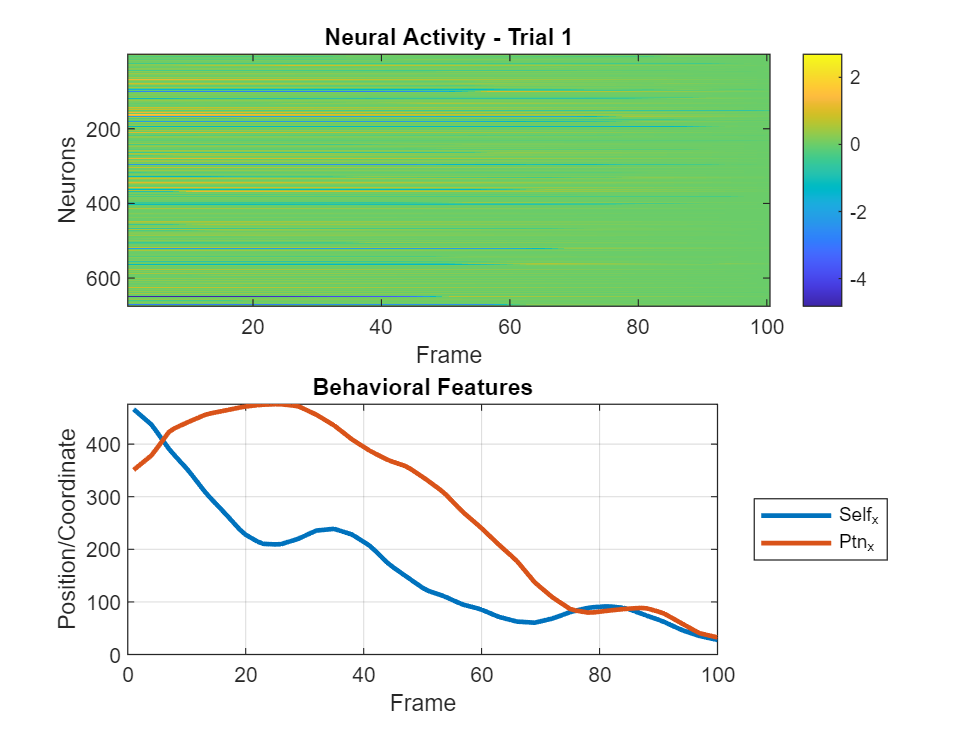

% plot an example trial with neural activity and features 
figure('Name', 'Example Trial Dynamics');
example_trial = 1; 
idx = find(trialid == example_trial);
subplot(2,1,1)
imagesc(neural(idx,:)')
title(['Neural Activity - Trial ', num2str(example_trial)])
ylabel('Neurons'); xlabel('Frame')
colorbar;
subplot(2,1,2)
plot(coop_features(idx, [1,3]), 'LineWidth', 2)
title('Behavioral Features')
legend(feature_keys([1,3]), 'Location', 'eastoutside')
ylabel('Position/Coordinate'); xlabel('Frame')
grid on

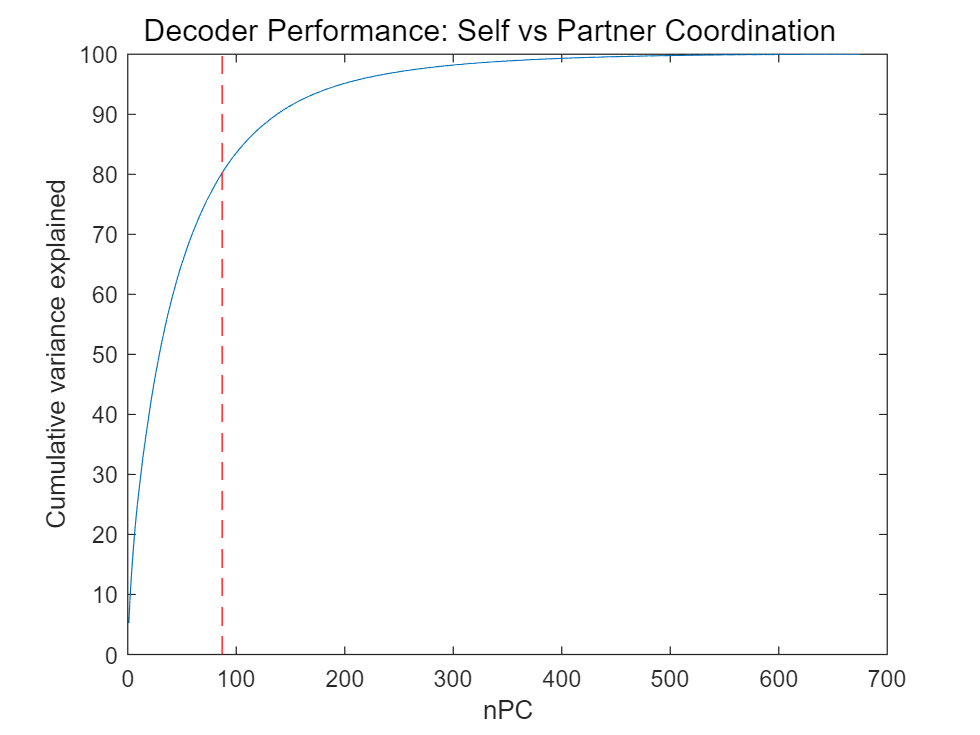

% run a PCA on the neural data to prevent overfitting - how many components
% takes 80% of variance?
[coeff,score,~,~,explained,mu] = pca(neural);
npc = find(cumsum(explained)>80,1);
% plot cumulative variance explained 
figure
plot(cumsum(explained)); hold on 
line([npc,npc],ylim,'Color','red','LineStyle','--'); xlabel('nPC'); 
ylabel('Cumulative variance explained')

% in practice, we perform PCA on the training set only, and apply the same
% weights on the test set. This is included in the code. 
nfold = 2;
[proj_train,proj_test,r2_train,r2_test,r2_testsh,pcc_test,pcc_testsh,mse,npc] = regression_shuffle(neural,coop_features,npc,nfold);

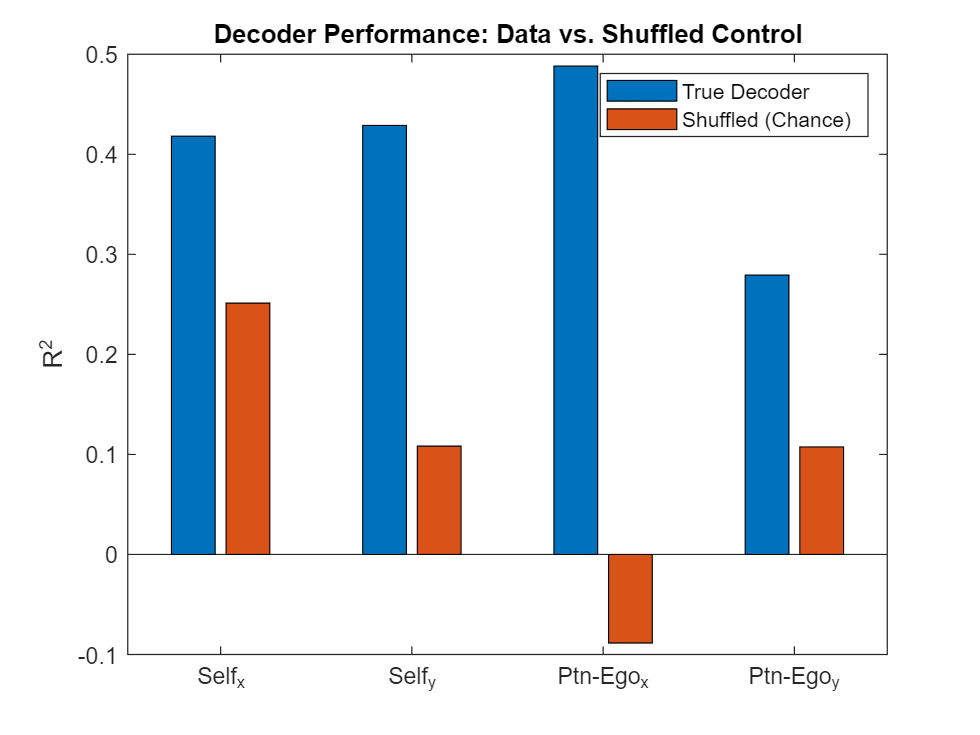

% Plot the decoder performance (R2) vs Shuffle
figure('Name', 'Decoder Performance Comparison');
data_to_plot = [r2_test', r2_testsh']; 
b = bar(data_to_plot([1,2,5,6],:), 'grouped');
set(gca, 'XTickLabel', feature_keys([1,2,5,6]));ylabel('R^2');
title('Decoder Performance: Data vs. Shuffled Control');
legend({'True Decoder', 'Shuffled (Chance)'}, 'Location', 'northeast');

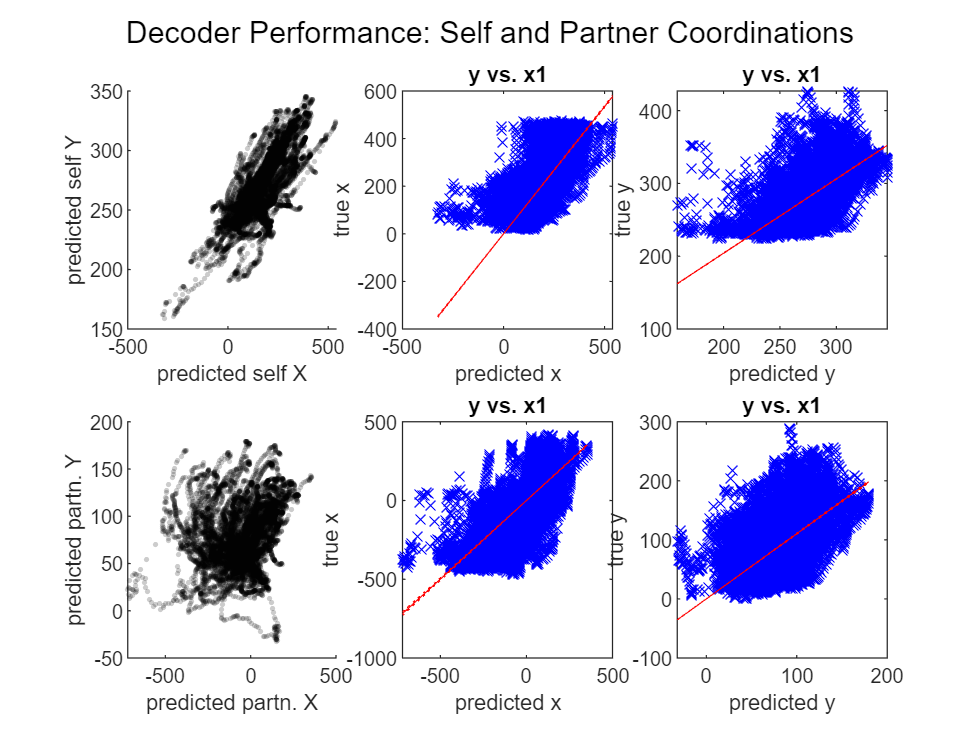

 %% plot on axis - self x and y
figure;sgtitle('Decoder Performance: Self and Partner Coordinations')
subplot(2,3,1)
scatter(proj_test(1,:),proj_test(2,:),5,'filled','MarkerFaceColor','k','MarkerFaceAlpha',0.2); hold on
xlabel('predicted self X'); ylabel('predicted self Y')
subplot(2,3,2)
mdl = fitlm(proj_test(1,:),coop_features(1:size(proj_test,2),1),'Intercept',false);
plot(mdl);legend off
xlabel('predicted x'); ylabel('true x');
%scatter(proj_test(5,:),features(test,5),5,"filled",'MarkerFaceAlpha',0.1);
subplot(2,3,3)
plot(fitlm(proj_test(2,:),coop_features(1:size(proj_test,2),2),'Intercept',false))
xlabel('predicted y'); ylabel('true y');legend off
%scatter(proj_test(6,:),features(test,6),5,"filled",'MarkerFaceAlpha',0.1);
% plot on axis - partner x and y
subplot(2,3,4)
scatter(proj_test(5,:),proj_test(6,:),5,'filled','MarkerFaceColor','k','MarkerFaceAlpha',0.2); hold on
xlabel('predicted partn. X'); ylabel('predicted partn. Y')
subplot(2,3,5)
mdl = fitlm(proj_test(5,:),coop_features(1:size(proj_test,2),5),'Intercept',false);
plot(mdl); legend off
xlabel('predicted x'); ylabel('true x');
%scatter(proj_test(5,:),features(test,5),5,"filled",'MarkerFaceAlpha',0.1);
subplot(2,3,6)
plot(fitlm(proj_test(6,:),coop_features(1:size(proj_test,2),6),'Intercept',false))
legend off
xlabel('predicted y'); ylabel('true y');

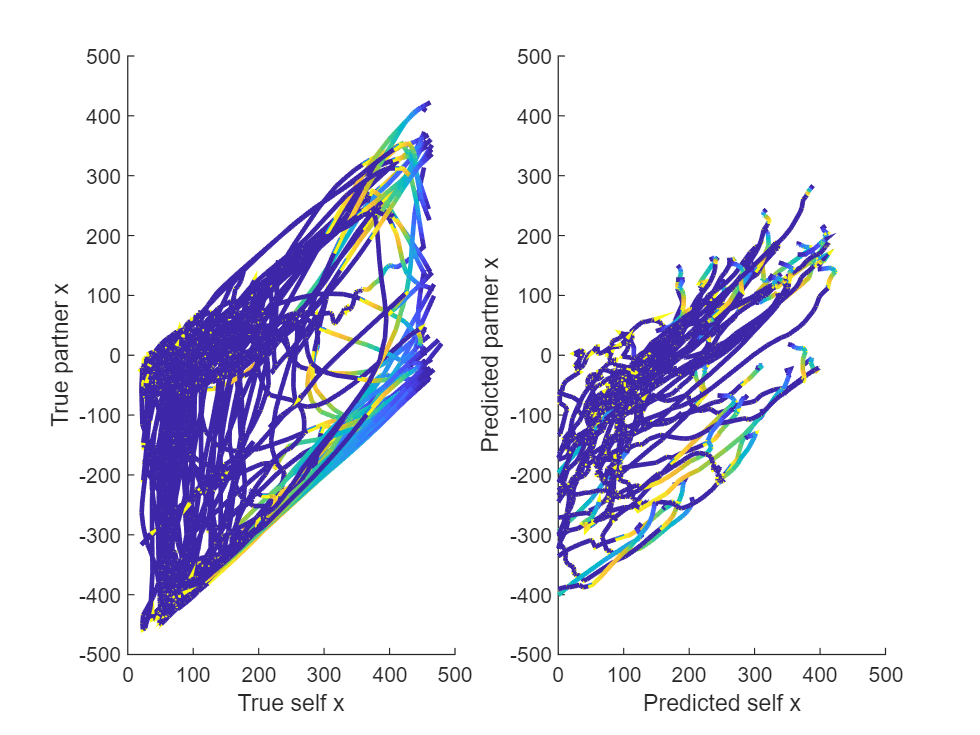

% plot the predicted and true trajectories
figure;
for i = 1:50
    subplot(1,2,1)
    x = coop_features(trialid==i,1)';
    y = coop_features(trialid==i,5)';
    z = zeros(size(x));
    col = 1:sum(trialid==i);
    patch([x, NaN], [y, NaN], [z, NaN], [col, NaN], ...
    'FaceColor', 'none', ...
    'EdgeColor', 'interp', ...
    'LineWidth', 2);
    xlim([0 500]); ylim([-500 500]); xlabel('True self x'); ylabel('True partner x')
    subplot(1,2,2)
    x = proj_test(1,trialid==i);
    y = proj_test(5,trialid==i);
    z = zeros(size(x));
    col = 1:sum(trialid==i);
    patch([x, NaN], [y, NaN], [z, NaN], [col, NaN], ...
    'FaceColor', 'none', ...
    'EdgeColor', 'interp', ...
    'LineWidth', 2);
    xlim([0 500]); ylim([-500 500]); xlabel('Predicted self x'); ylabel('Predicted partner x')
end

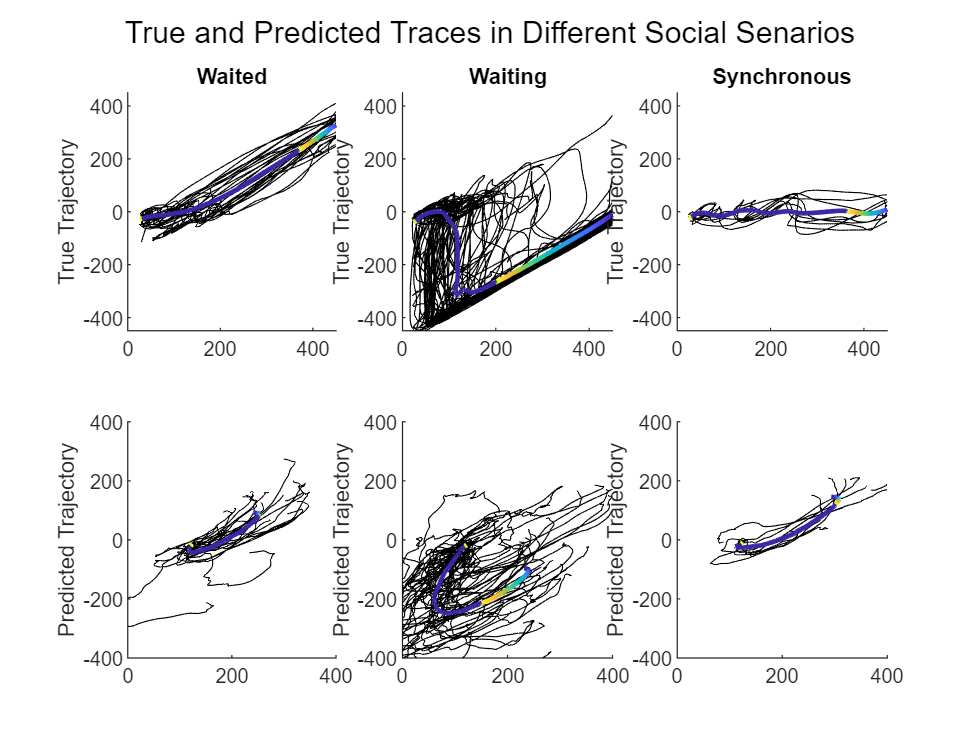

% Is that performance good / meaningful? 
% Let's break down the trials based on the behavioral dynamics of the
% two mice: to achieve a successful cooperation trial, they either move
% synchronous, or have to wait for each other. Let's see if the decoder can
% recover such social dynamics

% label the trials for waiting, waited and synchronous
trial = [];
warped_x = [];
warped_y = [];
warped_x_p = [];
warped_y_p = [];
for i = 1:trialid(end)
    x = coop_features(trialid==i,1)';
    y = coop_features(trialid==i,5)';
    z = zeros(size(x));
    col = 1:sum(trialid==i);
    % classify
    if y(15)< 0 && any(y<=-300)
        trial(i) = 2;
    elseif y(1)>= 250 && ~any(y<=-200)
        trial(i) = 1;
    elseif all(abs(y)<100)
        trial(i) = 3;
    elseif y(1)>= 250 && any(y<=-250)
        trial(i) = 4;
    else
        continue
    end
    % compute warp
    warped_x = [warped_x;interp1(0:1/(length(x)-1):1,x,0:1/199:1)];
    warped_y = [warped_y;interp1(0:1/(length(y)-1):1,y,0:1/199:1)];
    x = proj_test(1,trialid(1:length(proj_test))==i);
    y = proj_test(5,trialid(1:length(proj_test))==i);
    warped_x_p = [warped_x_p;interp1(0:1/(length(x)-1):1,x,0:1/199:1)];
    warped_y_p = [warped_y_p;interp1(0:1/(length(y)-1):1,y,0:1/199:1)];
end
% plot warped trace and average 
figure;sgtitle('True and Predicted Traces in Different Social Senarios')
titles = {'Waited', 'Waiting', 'Synchronous'};
trialmatch = trial(trial~=0);
for i = 1:3
    subplot(2,3,i)
    take = find(trialmatch == i);
    hl = plot(warped_x(take,:)',warped_y(take,:)','-','Color',[0, 0, 0, 0.2]);
    hold on
    x = mean(warped_x(take,:));
    y = mean(warped_y(take,:));
    z = zeros(size(x));
    col = 1:200;
    patch([x, NaN], [y, NaN], [z, NaN], [col, NaN], ...
    'FaceColor', 'none', ...
    'EdgeColor', 'interp', ...
    'LineWidth', 2);
    xlim([0 450]); ylim([-450 450]); box off
    title(titles{i}); ylabel('True Trajectory')
    subplot(2,3,3+i)
    take = find(trialmatch == i);
    hl = plot(warped_x_p(take,:)',warped_y_p(take,:)','-','Color',[0, 0, 0, 0.2]);
    hold on
    x = mean(warped_x_p(take,:));
    y = mean(warped_y_p(take,:));
    z = zeros(size(x));
    patch([x, NaN], [y, NaN], [z, NaN], [col, NaN], ...
    'FaceColor', 'none', ...
    'EdgeColor', 'interp', ...
    'LineWidth', 2);
    xlim([0 400]); ylim([-400 400]); box off
    ylabel('Predicted Trajectory')
end